# Feature_extraction.m (renamed variables, NN block added)

Naming scheme (locked in this revision): Cross-block signals: m_in (input), m_d (diff. output), m_c (counter output), m_out (NN output) Differentiator block: prefix D -> m_Df, m_Ds, reactions r_DF, r_DS, r_Dp, r_Di Counter block: prefix C -> m_Cs, reactions r_Cp, r_Cr, r_Cg NN block: prefix N -> m_Na, m_Nb, m_Nc, reactions r_Ni, r_Na, r_Nb, r_No

Three FLAGS embedded below — search for "FLAG" — call out kinetic choices that look like bugs in the current code and need a decision: FLAG-1: r_Di rate uses m_Df*m_Ds, not m_d*m_Ds (mass-action standard form) FLAG-2: m_Cs replenishment adds amplitude per step regardless of dt FLAG-3: m_Df and m_Ds have no degradation -> single-pulse only

clc;
clear;
close all;

fontsize = 15;

## =========================

Parameters ==========================

% --- Differentiator block (D) ---
% r_DF: emptyset -> m_Df         (fast tracker production)
pf      = 1;     % folding probability of the producing enzyme
k_DF    = 2;     % catalytic constant
K_DF    = 0.5;   % Michaelis constant
k_Df_deg = 0;    % FLAG-3: no decay

% r_DS: emptyset -> m_Ds         (slow tracker production)
ps      = 0.01;
k_DS    = 2;
K_DS    = 0.5;
k_Ds_deg = 0;    % FLAG-3: no decay

% r_Dp: emptyset -> m_d          (m_d production, gated by m_Df)
k_Dp    = 1;     % production rate
K_Dp    = 0.2;   % activation constant for m_Df -> m_d
n_Dp    = 1;     % Hill coefficient

% r_Di: m_d (+ m_Ds) -> sink     (sequestration / inhibition of m_d)
k_Di    = 20;    % rate constant
% FLAG-1: in the current code this rate uses m_Df*m_Ds. Standard mass-action
% would be k_Di * m_d * m_Ds. Both forms are kept below; toggle USE_STANDARD_RDI.
USE_STANDARD_RDI = false;

% --- Counter block (C) ---
% r_Cp:  m_d -> m_c              (catalytic in m_d, produces counter output)
V_Cp    = 1.0;
K_Cp    = 0.05;

% r_Cr:  m_c + m_Cs -> sink      (reset of m_c)
k_Cr    = 1.0;

% r_Cg:  m_d + m_Cs -> sink      (gating: m_d depletes m_Cs to silence reset during peak)
k_Cg    = 2.0;

% m_Cs supply (housekeeping)
m_Cs_amp = 0.009;   % FLAG-2: see m_Cs update line below

% --- NN block (N) ---
% Two-neuron NN per slide 16/17: r_Ni -> {r_Na, r_Nb} -> r_No.
% Each reaction is a Hill-activated production. Coefficients m_Na, m_Nb, m_Nc
% will be mapped to metabolite concentrations in Step 3.
%
% r_Ni: emptyset -> m_Ni   (input neuron, driven by m_c from the counter)
V_Ni    = 1.0;  K_Ni    = 0.1;  n_Ni = 2;

% r_Na: emptyset -> m_Na   (upper branch activation)
V_Na    = 1.0;  K_Na    = 0.1;  n_Na = 2;

% r_Nb: emptyset -> m_Nb   (lower branch activation)
V_Nb    = 1.0;  K_Nb    = 0.1;  n_Nb = 2;

% r_No: emptyset -> m_out  (output neuron, combines m_Na and m_Nb with weight m_Nc)
V_No    = 1.0;  K_No    = 0.1;  n_No = 2;

% Network "weights" (slide-16 coefficients m_2, m_3, m_4 in old notation)
m_Nc_const = 1.0;   % shared post-activation coefficient; constant for now

% Housekeeping decays for NN species (so they relax between bits)
k_Ni_deg = 1.0; k_Na_deg = 1.0; k_Nb_deg = 1.0; k_out_deg = 1.0;

% --- Communication channel ---
M_0  = 1e4;        % transmitter concentration
D_co = 66e-13;     % diffusion coefficient (tumor extracellular vesicle)
d    = 20e-6;      % distance between emitter and receiver
Tp   = 2;          % pulse duration [s]
Ts   = 0.01;       % sampling time
fs   = 1/Ts;
sequence = [1 0 0 0 0 0 0 0 0 0 0 0 0];
r_rx = 0.15e-6;
V_rx = 4/3*pi*r_rx^3;

## =========================

Time vector and Tx waveform ==========================

samples_per_pulse = floor(Tp * fs);
total_samples     = length(sequence) * samples_per_pulse;
t   = (0:total_samples-1)' / fs;
mTx = repelem(sequence, samples_per_pulse)' * M_0;

## =========================

Diffusion channel -> received concentration m_in ==========================

t_h = t; t_h(1) = 1/fs;
h   = V_rx ./ (4*pi*D_co*t_h).^(3/2) .* exp(-d^2 ./ (4*D_co*t_h));
m_in = conv(h, mTx);
m_in = m_in(1:length(t));

## =========================

State arrays ==========================

N = length(t);

% Differentiator block
m_Df = zeros(N,1);    % fast tracker
m_Ds = zeros(N,1);    % slow tracker
m_d  = zeros(N,1);    % differentiator output (cross-block signal)

% Counter block
m_c  = zeros(N,1);                  % counter output (cross-block signal)
m_Cs = m_Cs_amp * ones(N,1);        % counter's stop signal

% NN block
m_Ni = zeros(N,1);    % input-neuron internal
m_Na = zeros(N,1);    % upper-branch activation
m_Nb = zeros(N,1);    % lower-branch activation
m_out = zeros(N,1);   % NN output (cross-block signal)

% Diagnostic intermediates kept for plotting
v_Dp = zeros(N,1);
v_Di = zeros(N,1);

## =========================

Discrete-time simulation ==========================

for n = 1:N-1

    dt = t(n+1) - t(n);

    % ============================================================
    % DIFFERENTIATOR BLOCK
    % ============================================================
    % r_DF: emptyset -> m_Df
    v_DF = pf * k_DF * ( m_in(n) / (K_DF + m_in(n)) );
    m_Df(n+1) = max( m_Df(n) + dt * ( v_DF - k_Df_deg * m_Df(n) ), 0 );

    % r_DS: emptyset -> m_Ds
    v_DS = ps * k_DS * ( m_in(n) / (K_DS + m_in(n)) );
    m_Ds(n+1) = max( m_Ds(n) + dt * ( v_DS - k_Ds_deg * m_Ds(n) ), 0 );

    % r_Dp: emptyset -> m_d   (Hill-activation by m_Df)
    act_Dp = (m_Df(n)^n_Dp) / (K_Dp^n_Dp + m_Df(n)^n_Dp);
    v_Dp(n+1) = k_Dp * act_Dp;

    % r_Di: m_d (+ m_Ds) -> sink
    % v_Di(n+1) = k_Di * m_Df(n) * m_Ds(n);    % FLAG-1: legacy form (m_Df instead of m_d)
    v_Di(n+1) = k_Di * m_Ds(n);    % FLAG-1: legacy form (m_Df instead of m_d)
 

    m_d(n+1) = max( m_d(n) + dt * ( v_Dp(n+1) - v_Di(n+1) ), 0 );

    % ============================================================
    % COUNTER BLOCK
    % ============================================================
    % r_Cp:  m_d -> m_c   (catalytic; m_d not consumed in this rate law)
    v_Cp = V_Cp * m_d(n) / (K_Cp + m_d(n));

    % r_Cr:  m_c + m_Cs -> sink
    v_Cr = k_Cr * m_c(n) * m_Cs(n);

    % r_Cg:  m_d + m_Cs -> sink
    v_Cg = k_Cg * m_d(n) * m_Cs(n);

    % update m_c
    m_c(n+1) = max( m_c(n) + dt * ( v_Cp - v_Cr ), 0 );

    % update m_Cs
    m_Cs(n+1) = max( m_Cs(n) - dt*v_Cg + m_Cs_amp, 0 );
  

    % ============================================================
    % NN BLOCK  (2-neuron NN per slides 16-17)
    % ============================================================
    % Input neuron r_Ni: driven by m_c
    act_Ni = (m_c(n)^n_Ni) / (K_Ni^n_Ni + m_c(n)^n_Ni);
    v_Ni   = V_Ni * act_Ni;
    m_Ni(n+1) = max( m_Ni(n) + dt*( v_Ni - k_Ni_deg * m_Ni(n) ), 0 );

    % Upper branch r_Na: activated by m_Ni
    act_Na = (m_Ni(n)^n_Na) / (K_Na^n_Na + m_Ni(n)^n_Na);
    v_Na   = V_Na * act_Na;
    m_Na(n+1) = max( m_Na(n) + dt*( v_Na - k_Na_deg * m_Na(n) ), 0 );

    % Lower branch r_Nb: activated by m_Ni
    act_Nb = (m_Ni(n)^n_Nb) / (K_Nb^n_Nb + m_Ni(n)^n_Nb);
    v_Nb   = V_Nb * act_Nb;
    m_Nb(n+1) = max( m_Nb(n) + dt*( v_Nb - k_Nb_deg * m_Nb(n) ), 0 );

    % Output neuron r_No: combines m_Na and m_Nb (weighted by m_Nc constant)
    drive_No = m_Nc_const * (m_Na(n) + m_Nb(n));
    act_No   = (drive_No^n_No) / (K_No^n_No + drive_No^n_No);
    v_No     = V_No * act_No;
    m_out(n+1) = max( m_out(n) + dt*( v_No - k_out_deg * m_out(n) ), 0 );

end

## =========================

Plot 1: Received signal m_in and differentiator output m_d ==========================

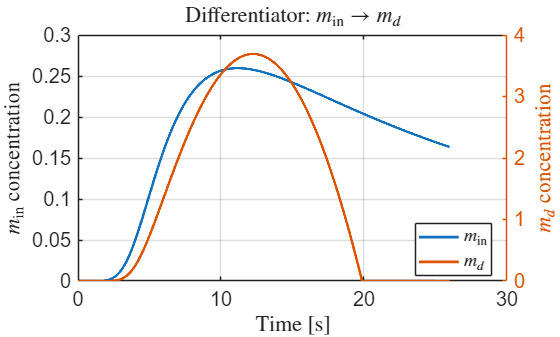

figure;
plot(t, m_in, 'LineWidth', 2); hold on;
ylabel('$m_\mathrm{in}$ concentration', 'Interpreter', 'latex');
yyaxis right
plot(t, m_d, 'LineWidth', 2);
ylabel('$m_d$ concentration', 'Interpreter', 'latex');
xlabel('Time [s]', 'Interpreter', 'latex');
legend({'$m_\mathrm{in}$', '$m_d$'}, 'Interpreter', 'latex', 'Location', 'best');
set(gca, 'FontSize', fontsize); grid on;
title('Differentiator: $m_\mathrm{in}\rightarrow m_d$', 'Interpreter', 'latex');

## =========================

Plot 2: Counter output m_c ==========================

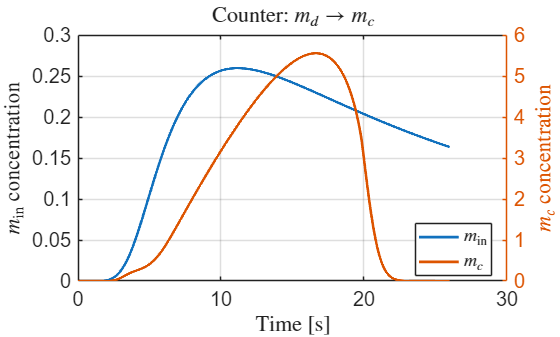

figure;
plot(t, m_in, 'LineWidth', 2);
ylabel('$m_\mathrm{in}$ concentration', 'Interpreter', 'latex');
yyaxis right
plot(t, m_c, 'LineWidth', 2); hold on;
ylabel('$m_c$ concentration', 'Interpreter', 'latex');
xlabel('Time [s]', 'Interpreter', 'latex');
legend({'$m_\mathrm{in}$', '$m_c$'}, 'Interpreter', 'latex', 'Location', 'best');
% axis([0 t(end) 0 5]);
set(gca, 'FontSize', fontsize); grid on;
title('Counter: $m_d\rightarrow m_c$', 'Interpreter', 'latex');

## =========================

Plot 3: NN response ==========================

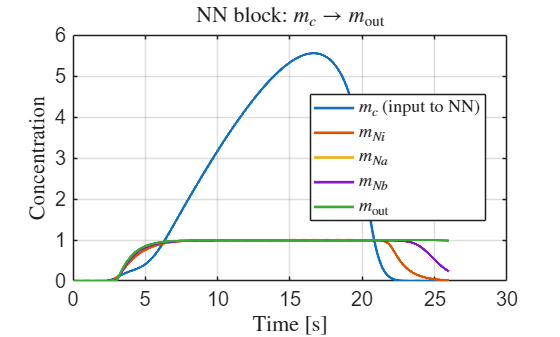

figure;
plot(t, m_c, 'LineWidth', 2); hold on;
plot(t, m_Ni, 'LineWidth', 2);
plot(t, m_Na, 'LineWidth', 2);
plot(t, m_Nb, 'LineWidth', 2);
plot(t, m_out, 'LineWidth', 2);
xlabel('Time [s]', 'Interpreter', 'latex');
ylabel('Concentration', 'Interpreter', 'latex');
legend({'$m_c$ (input to NN)', '$m_{Ni}$', '$m_{Na}$', '$m_{Nb}$', '$m_\mathrm{out}$'}, ...
       'Interpreter', 'latex', 'Location', 'best');
set(gca, 'FontSize', fontsize); grid on;
title('NN block: $m_c\rightarrow m_\mathrm{out}$', 'Interpreter', 'latex');